## More tinkering with theory:

Trying to understand how to decouple the coupled PDEs in general. The coupling is through the linear algebra (off-diagonal matrix terms) and the calculus. How is that decoupled/separated in general?

Write the derivative operators as algebraic multipliers and see where it leads:

clear all
syms x y real
syms t real positive
syms f g H real positive
syms k l K omega real
syms d_x d_y d_t eta_x eta_y

Look at (u,v) system only, with given RHS

A = [[d_t,-f]
    [f,d_t]]

$$A = \left(\begin{array}{cc} d_{t} & -f\\ f & d_{t} \end{array}\right)$$

inv(A)

$$ans = \left(\begin{array}{cc} \frac{d_{t}}{{d_{t}}^{2}+f^{2}} & \frac{f}{{d_{t}}^{2}+f^{2}}\\ -\frac{f}{{d_{t}}^{2}+f^{2}} & \frac{d_{t}}{{d_{t}}^{2}+f^{2}} \end{array}\right)$$

y = -g*[eta_x ; eta_y]

$$y = \left(\begin{array}{c} -\eta_{x}\,g\\ -\eta_{y}\,g \end{array}\right)$$

A\y

$$ans = \left(\begin{array}{c} -\frac{g\,\left(d_{t}\,\eta_{x}+\eta_{y}\,f\right)}{{d_{t}}^{2}+f^{2}}\\ -\frac{g\,\left(d_{t}\,\eta_{y}-\eta_{x}\,f\right)}{{d_{t}}^{2}+f^{2}} \end{array}\right)$$

This last result means (d_t^2 + f^2)[u; v] = the numerator of ans, A\y. This decouples the equations. 

Now look at full 3x3 RSW system:

A = [[d_t -f g*d_x]
    [f d_t g*d_y]
    [H*d_x H*d_y d_t]]

$$A = \left(\begin{array}{ccc} d_{t} & -f & d_{x}\,g\\ f & d_{t} & d_{y}\,g\\ H\,d_{x} & H\,d_{y} & d_{t} \end{array}\right)$$

inv(A./det(A))

$$ans = \left(\begin{array}{ccc} {d_{t}}^{2}-H\,{d_{y}}^{2}\,g & d_{t}\,f+H\,d_{x}\,d_{y}\,g & -g\,\left(d_{t}\,d_{x}+d_{y}\,f\right)\\ H\,d_{x}\,d_{y}\,g-d_{t}\,f & {d_{t}}^{2}-H\,{d_{x}}^{2}\,g & -g\,\left(d_{t}\,d_{y}-d_{x}\,f\right)\\ -H\,\left(d_{t}\,d_{x}-d_{y}\,f\right) & -H\,\left(d_{t}\,d_{y}+d_{x}\,f\right) & {d_{t}}^{2}+f^{2} \end{array}\right)$$

det(A)

$$ans = {d_{t}}^{3}-H\,g\,d_{t}\,{d_{x}}^{2}-H\,g\,d_{t}\,{d_{y}}^{2}+d_{t}\,f^{2}$$

The determinant gives the operator that uncouples the equations.

#### Variation on the above where the time dependence is assumed to be oscillatory:

A = [[1i*omega -f g*d_x]
    [f 1i*omega g*d_y]
    [H*d_x H*d_y 1i*omega]]

$$A = \left(\begin{array}{ccc} \omega \,\mathrm{i} & -f & d_{x}\,g\\ f & \omega \,\mathrm{i} & d_{y}\,g\\ H\,d_{x} & H\,d_{y} & \omega \,\mathrm{i} \end{array}\right)$$

det(A)

$$ans = -\mathrm{i}\,H\,g\,{d_{x}}^{2}\,\omega -\mathrm{i}\,H\,g\,{d_{y}}^{2}\,\omega +f^{2}\,\omega \,\mathrm{i}-\omega^{3}\,\mathrm{i}$$

Written as $\nabla^2 + K^2$, this gives Taylor (1922) eqn. (1d) and the dispersion relation $\omega^2 = f^2 + g H K^2$ or $\omega = 0$.

This inverse matrix and determinant says add "-gH*d_yy of the u-eqn to gH d_xy of the v eqn to give gH*(f d_xy - i omega d_yy) of u" (and the gH can be cancelled).

#### Check Infinite plane $\eta, v$ field gives the correct initial condition:

syms k x omega t real
expr_e = (k/(1+k^2))*sin(k*x)

$$expr\_e = \frac{k\,\sin\left(k\,x\right)}{k^{2}+1}$$

tmp_e = simplify((2/pi)*int(expr_e,k,[0 Inf]) + sign(x)*(1 - exp(-abs(x)))) ;
fplot(tmp_e,'b-','linewidth',2); xlabel('$x$','Interpreter',"latex"); ylabel('$\eta, v$','Interpreter',"latex"); hold on
expr_v = (1/(1+k^2))*cos(k*x)

$$expr\_v = \frac{\cos\left(k\,x\right)}{k^{2}+1}$$

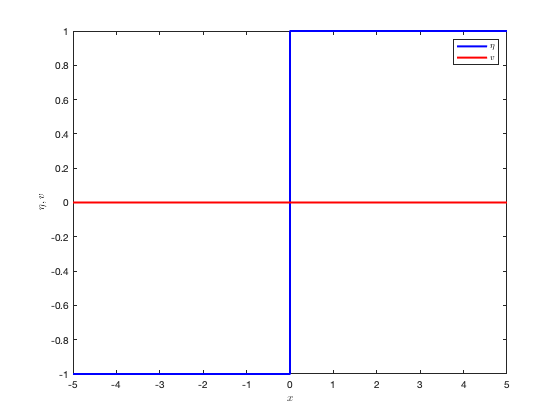

tmp_v = simplify((2/pi)*int(expr_v,k,[0 Inf]) - exp(-abs(x))) ;
fplot(tmp_v,'r-','linewidth',2); xlabel('$x$','Interpreter',"latex"); legend('$\eta$','$v$','interpreter','latex')

## Testing ideas in Kelvin wave derivation. 

How is Thomson's solution from the maths found without physical intuition?

clear all
syms x y k l Delta_eta omega real
syms f g H M t real positive

Thomson's (1888) Kelvin wave expressions in a channel:

eta = Delta_eta*(exp(-l*y)*cos(k*x - omega*t) - exp(l*y)*cos(k*x + omega*t))

$$eta = -\Delta_{\eta }\,\left(\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{l\,y}-\cos\left(k\,x-\omega \,t\right)\,{\mathrm{e}}^{-l\,y}\right)$$

v = 0 ;
u = (g*k*Delta_eta/omega)*(exp(-l*y)*cos(k*x - omega*t) + exp(l*y)*cos(k*x + omega*t))

$$u = \frac{\Delta_{\eta }\,g\,k\,\left(\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{l\,y}+\cos\left(k\,x-\omega \,t\right)\,{\mathrm{e}}^{-l\,y}\right)}{\omega }$$

These should all be zero so the RSW dynamical equations are satisfied, so long as $\frac{1}{l} = \frac{\sqrt{ g H}}{ f}$ and$\left(\frac{\omega}{k}\right)^2 = g H$

rhs_u = simplify(diff(u,t) - f*v + g*diff(eta,x))

$$rhs\_u = 0$$

rhs_v = simplify(diff(v,t) + f*u + g*diff(eta,y)) ;
rhs_v = subs(rhs_v,l,f/sqrt(g*H)) ;
rhs_v = subs(rhs_v,omega,k*sqrt(g*H))

$$rhs\_v = 0$$

rhs_e = simplify(diff(eta,t) + H*(diff(u,x) + diff(v,y))) ;
rhs_e = subs(rhs_e,omega^2,k*k*g*H)

$$rhs\_e = 0$$

Thomson's soln **doesn't** satisfy the Helmholtz equation with an arbitrary $l$!

rhs_Helmholtz_u = simplify(diff(  u,y,y) + l^2*  u)

$$rhs\_Helmholtz\_u = \frac{2\,\Delta_{\eta }\,g\,k\,l^{2}\,\left(\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{l\,y}+\cos\left(k\,x-\omega \,t\right)\,{\mathrm{e}}^{-l\,y}\right)}{\omega }$$

rhs_Helmholtz_e = simplify(diff(eta,y,y) + l^2*eta)

$$rhs\_Helmholtz\_e = 2\,\Delta_{\eta }\,l^{2}\,{\mathrm{e}}^{-l\,y}\,\left(\cos\left(k\,x-\omega \,t\right)-\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{2\,l\,y}\right)$$

Thomson's soln **does** satisfy the Helmholtz equation with $\left(\frac{\omega}{k}\right)^2 = gH$ and $l^2 = \frac{g H}{f}$.

rhs_Helmholtz_u = simplify(diff(  u,y,y) - (k^2 - (omega^2 - f^2)/(g*H))*  u)

$$rhs\_Helmholtz\_u = -\frac{\Delta_{\eta }\,k\,{\mathrm{e}}^{-l\,y}\,\left(\cos\left(k\,x-\omega \,t\right)+\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{2\,l\,y}\right)\,\left(f^{2}+H\,g\,k^{2}-H\,g\,l^{2}-\omega^{2}\right)}{H\,\omega }$$

rhs_Helmholtz_e = simplify(diff(eta,y,y) - (k^2 - (omega^2 - f^2)/(g*H))*eta)

$$rhs\_Helmholtz\_e = -\frac{\Delta_{\eta }\,{\mathrm{e}}^{-l\,y}\,\left(\cos\left(k\,x-\omega \,t\right)-\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{2\,l\,y}\right)\,\left(f^{2}+H\,g\,k^{2}-H\,g\,l^{2}-\omega^{2}\right)}{H\,g}$$

Thomson's soln **does** satisfy the Klein-Gordon equation with $\left(\frac{\omega}{k}\right)^2 = gH$ and $l^2 = \frac{g H}{f}$.

rhs_KleinGordon_u = simplify(diff(  u,t,t) - g*H*(diff(  u,x,x) + diff(  u,y,y)) + f^2*  u)

$$rhs\_KleinGordon\_u = \frac{\Delta_{\eta }\,g\,k\,{\mathrm{e}}^{-l\,y}\,\left(\cos\left(k\,x-\omega \,t\right)+\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{2\,l\,y}\right)\,\left(f^{2}+H\,g\,k^{2}-H\,g\,l^{2}-\omega^{2}\right)}{\omega }$$

rhs_KleinGordon_e = simplify(diff(eta,t,t) - g*H*(diff(eta,x,x) + diff(eta,y,y)) + f^2*eta)

$$rhs\_KleinGordon\_e = \Delta_{\eta }\,{\mathrm{e}}^{-l\,y}\,\left(\cos\left(k\,x-\omega \,t\right)-\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{2\,l\,y}\right)\,\left(f^{2}+H\,g\,k^{2}-H\,g\,l^{2}-\omega^{2}\right)$$

Check Thomson's bcs. How could these be specified *a priori* without knowing the solution?

e_bcm = simplify(subs(eta,y,-M/2))

$$e\_bcm = -\Delta_{\eta }\,\left(\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{-\frac{M\,l}{2}}-\cos\left(k\,x-\omega \,t\right)\,{\mathrm{e}}^{\frac{M\,l}{2}}\right)$$

e_bcp = simplify(subs(eta,y, M/2))

$$e\_bcp = -\Delta_{\eta }\,\left(\cos\left(k\,x+\omega \,t\right)\,{\mathrm{e}}^{\frac{M\,l}{2}}-\cos\left(k\,x-\omega \,t\right)\,{\mathrm{e}}^{-\frac{M\,l}{2}}\right)$$

u_bcm = simplify(subs(  u,y,-M/2)) ;
u_bcp = simplify(subs(  u,y, M/2)) ;

Check calculation of channel IGW modes

clear all
syms y k real
syms M g f H m L_r omega real positive
syms n integer
assumeAlso(n >= 0) ;
syms c_n
V_hat = c_n*cos(m*y) ;
syms U_hat(y) E_hat(y) d_E_hat(y)

Define equations and substitute:

eqn1 = -1i*omega*U_hat -f*V_hat - 1i*k*g*E_hat == 0 

$$eqn1(y) = -\omega \,\hat{U}\left(y\right)\,\mathrm{i}-c_{n}\,f\,\cos\left(m\,y\right)-g\,k\,\hat{E}\left(y\right)\,\mathrm{i}=0$$

eqn2 = f*U_hat - 1i*omega*V_hat + g*d_E_hat == 0 

$$eqn2(y) = f\,\hat{U}\left(y\right)+g\,d_{\hat{E}}\left(y\right)-c_{n}\,\omega \,\cos\left(m\,y\right)\,\mathrm{i}=0$$

eqn3 = -1i*k*H*U_hat + H*diff(V_hat,y) - 1i*omega*E_hat == 0

$$eqn3(y) = -H\,c_{n}\,m\,\sin\left(m\,y\right)-\omega \,\hat{E}\left(y\right)\,\mathrm{i}-H\,k\,\hat{U}\left(y\right)\,\mathrm{i}=0$$

Solve 3 eqns for U_hat and E_hat

U_hat_tmp = isolate(eqn1,U_hat) ;
eqn2b     = simplify(subs(eqn2,U_hat,rhs(U_hat_tmp))) ;
eqn3b     = simplify(subs(eqn3,U_hat,rhs(U_hat_tmp))) ;
E_hat_iso = simplify(rhs(isolate(eqn3b,E_hat)))

$$E\_hat\_iso = -\frac{H\,c_{n}\,\left(f\,k\,\cos\left(m\,y\right)-m\,\omega \,\sin\left(m\,y\right)\right)\,\mathrm{i}}{\omega^{2}-H\,g\,k^{2}}$$

U_hat_iso = simplify(subs(rhs(U_hat_tmp),E_hat,E_hat_iso))

$$U\_hat\_iso = \frac{c_{n}\,\left(f\,\omega \,\cos\left(m\,y\right)\,\mathrm{i}-H\,g\,k\,m\,\sin\left(m\,y\right)\,\mathrm{i}\right)}{\omega^{2}-H\,g\,k^{2}}$$

tmp = subs(eqn2b,E_hat,E_hat_iso) ;
simplify(subs(tmp,d_E_hat,diff(E_hat_iso,y)))       % This is the condition to satisfy eqn2 (satisfied for IGWs)

$$ans(y) = \omega^{2}\neq H\,g\,k^{2}\wedge \left(c_{n}=0\vee f^{2}\,\mathrm{i}+\mathrm{i}\,H\,g\,k^{2}+\mathrm{i}\,H\,g\,m^{2}=\omega^{2}\,\mathrm{i}\vee \frac{\pi -2\,m\,y}{2\,\pi }\in \mathbb{Z}\right)$$

## Integrals over trigonometric functions and matrix inverses

clear all
syms m Delta_eta L_r M g H real positive
syms x y k omega real
syms n real integer
syms A B C
assumeAlso(n >= 0) ;
m = (2*n + 1)*pi/M ;
exprc = simplify(int(cos(m*y)*exp( y/L_r),y,[-M/2 M/2]))         % This is the same if it's exp(-y/L_r)

$$exprc = \frac{2\,\pi \,{\left(-1\right)}^{n}\,{L_{r}}^{2}\,M\,\cosh\left(\frac{M}{2\,L_{r}}\right)\,\left(2\,n+1\right)}{4\,\pi^{2}\,{L_{r}}^{2}\,n^{2}+4\,\pi^{2}\,{L_{r}}^{2}\,n+\pi^{2}\,{L_{r}}^{2}+M^{2}}$$

exprsm = simplify(int(sin(m*y)*exp(-y/L_r),y,[-M/2 M/2]))

$$exprsm = -\frac{2\,{\left(-1\right)}^{n}\,L_{r}\,M^{2}\,\cosh\left(\frac{M}{2\,L_{r}}\right)}{4\,\pi^{2}\,{L_{r}}^{2}\,n^{2}+4\,\pi^{2}\,{L_{r}}^{2}\,n+\pi^{2}\,{L_{r}}^{2}+M^{2}}$$

exprsp = simplify(int(sin(m*y)*exp( y/L_r),y,[-M/2 M/2]))

$$exprsp = \frac{2\,{\left(-1\right)}^{n}\,L_{r}\,M^{2}\,\cosh\left(\frac{M}{2\,L_{r}}\right)}{4\,\pi^{2}\,{L_{r}}^{2}\,n^{2}+4\,\pi^{2}\,{L_{r}}^{2}\,n+\pi^{2}\,{L_{r}}^{2}+M^{2}}$$

simplify(int(cos(k*x)/(1+L_r^2*(k^2 + m^2)),k,[0 Inf])) % No closed form for this integral

$$ans = \int_{0}^{\infty }\frac{\cos\left(k\,x\right)}{\left(k^{2}+\frac{\pi^{2}\,{\left(2\,n+1\right)}^{2}}{M^{2}}\right)\,{L_{r}}^{2}+1}\mathrm{d}k$$

expr_cosh_cosine_series = simplify(int(cos(m*y)*cosh(y/L_r),y,[-M/2 M/2])) % expansion in a cosine series gives gamma_n

$$expr\_cosh\_cosine\_series = \frac{2\,\pi \,{\left(-1\right)}^{n}\,{L_{r}}^{2}\,M\,\cosh\left(\frac{M}{2\,L_{r}}\right)\,\left(2\,n+1\right)}{4\,\pi^{2}\,{L_{r}}^{2}\,n^{2}+4\,\pi^{2}\,{L_{r}}^{2}\,n+\pi^{2}\,{L_{r}}^{2}+M^{2}}$$

Orthogonality integrals

syms np real integer
assumeAlso(np > 0)
mp = (2*np + 1)*pi/M ;
expr = int(cos(m*y)*cos(mp*y),y,[-M/2 M/2])

$$expr = \left\{ \begin{array}{cl} \frac{M}{2} & \text{ if }n=\mathrm{np}\\ 0 & \text{ if }n\neq \mathrm{np} \end{array}\right.$$

expr = int(sin(m*y)*sin(mp*y),y,[-M/2 M/2])

$$expr = \left\{ \begin{array}{cl} \frac{M}{2} & \text{ if }n=\mathrm{np}\\ 0 & \text{ if }n\neq \mathrm{np} \end{array}\right.$$

expr = int(sin(m*y)*cos(mp*y),y,[-M/2 M/2])

$$expr = 0$$

expr = int(sin(m*y),y,[-M/2 M/2])

$$expr = 0$$

expr = simplify(int(cos(m*y),y,[-M/2 M/2]))

$$expr = \frac{2\,{\left(-1\right)}^{n}\,M}{\pi \,\left(2\,n+1\right)}$$

Matrix inverses:

A = 1i.*[-omega, k*g; k*H, -omega]

$$A = \left(\begin{array}{cc} -\omega \,\mathrm{i} & g\,k\,\mathrm{i}\\ H\,k\,\mathrm{i} & -\omega \,\mathrm{i} \end{array}\right)$$

inv(A)

$$ans = \left(\begin{array}{cc} -\frac{\omega }{\omega^{2}\,\mathrm{i}-H\,g\,k^{2}\,\mathrm{i}} & -\frac{g\,k}{\omega^{2}\,\mathrm{i}-H\,g\,k^{2}\,\mathrm{i}}\\ -\frac{H\,k}{\omega^{2}\,\mathrm{i}-H\,g\,k^{2}\,\mathrm{i}} & -\frac{\omega }{\omega^{2}\,\mathrm{i}-H\,g\,k^{2}\,\mathrm{i}} \end{array}\right)$$

B = [sqrt(g/H), -sqrt(g/H); -1, -1]

$$B = \left(\begin{array}{cc} \frac{\sqrt{g}}{\sqrt{H}} & -\frac{\sqrt{g}}{\sqrt{H}}\\ -1 & -1 \end{array}\right)$$

inv(B)

$$ans = \left(\begin{array}{cc} \frac{\sqrt{H}}{2\,\sqrt{g}} & -\frac{1}{2}\\ -\frac{\sqrt{H}}{2\,\sqrt{g}} & -\frac{1}{2} \end{array}\right)$$

C = [sqrt(g/H),  sqrt(g/H); -1,  1]

$$C = \left(\begin{array}{cc} \frac{\sqrt{g}}{\sqrt{H}} & \frac{\sqrt{g}}{\sqrt{H}}\\ -1 & 1 \end{array}\right)$$

inv(C)

$$ans = \left(\begin{array}{cc} \frac{\sqrt{H}}{2\,\sqrt{g}} & -\frac{1}{2}\\ \frac{\sqrt{H}}{2\,\sqrt{g}} & \frac{1}{2} \end{array}\right)$$

## Check Fourier series expansions of cosh and sinh 

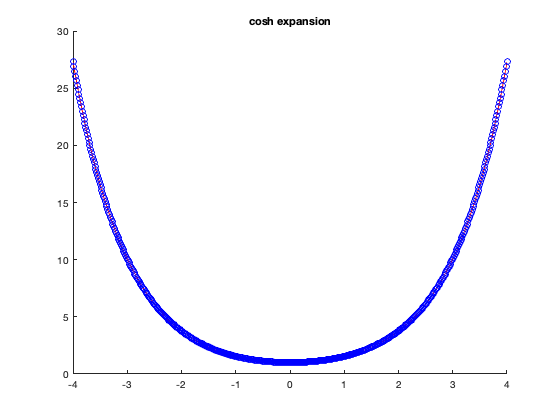

clear all
M = 8 ;
N = 10 ;
n = 0:2^N ;
m = (2*n+1)*pi/M ;
y = linspace(-M/2,M/2,2^(N-1)) ;
[ns,  ~] = ndgrid(n,y) ;
[ms, ys] = ndgrid(m,y) ;
m_y = ms.*ys ;
cosh_terms = (4.*((-1).^ns)./(M*ms.*(1 + ms.^2))).*cos(m_y) ;
cosh_sum   = cosh(M/2)*(1 - sum(cosh_terms,1)) ;
sinh_terms = (4.*((-1).^ns)./(1 + ms.^2))*(cosh(M/2)/M).*sin(m_y) ;
sinh_sum   = sum(sinh_terms,1) ;

figure
hold on
title('cosh expansion')
plot(y,cosh(y),'r-')
plot(y,cosh_sum,'bo')

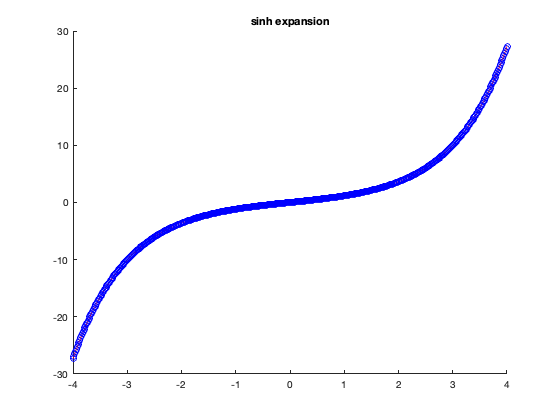


figure
hold on
title('sinh expansion')
plot(y,sinh(y),'r-')
plot(y,sinh_sum,'bo')

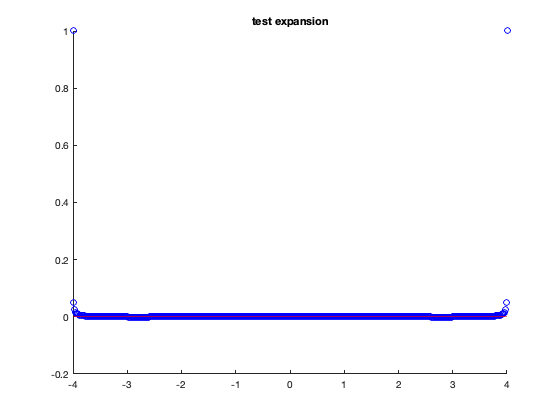

test_terms = (4.*((-1).^ns)./(M*ms)).*cos(m_y) ;
test_sum   = 1 - sum(test_terms,1) ;

figure
hold on
title('test expansion')
plot(y,test_sum,'bo')
plot(y,zeros(size(y)),'r-')